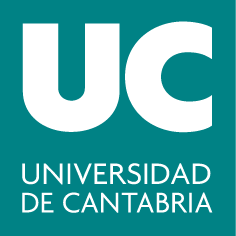

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometria**

# ** Sistemas de ecuaciones lineales indeterminados**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Uso de variables simbólicas en MATLAB

- Resolución de sistemas compatibles indeterminados

- Resolución de sistemas homogénos 

**Funciones de MATLAB utilizadas en este guion: **`rank, solve, null, rref, class, double, subs.`

Una vez visto como resolver los sistemas compatibles determinados (SCD), en este guion veremos como hallar la solución general de sistemas compatibles indeterminados (SCI). Puesto que para obtener dicha solución general necesitamos el uso de variables simbólicas, este guion comienza con una introducción al uso de variables simbólicas en MATLAB.

## **1.1 Definición de variables y expresiones simbólicas**

MATLAB permite trabajar con variables simbólicas, es decir, variables genéricas que, en principio, no tienen por qué tomar un valor concreto. Para declarar una variable simbólica usamos el comando `syms` seguido del nombre que queremos asignar a la variable simbólica.

% defino la variable 'x' como simbólica
syms x  % syms('x') es otra sintaxis válida

Podemos definir expresiones utilizando las variables simbólicas, estas serán expresiones simbólicas.

ex = x^2 + 5  % expresión que depende de 'x'

Por depender de la variable simbólica *x, ex *será una expresión simbólica. Podemos comprobar de qué tipo es una variable dada con el comando `class`*,* que nos devuelve el tipo o clase de una variable:

class(x)  % 'x' es una variable simbólica (sym)
class(ex) % 'eq' es una expresión simbólica (sym)
a=2;
class(a) % a es una variable numerica tipo double

### 1.2 Función subs: asignación de valores a variables simbólicas

Podemos hacer que una variable simbólica tome un valor concreto con la función `subs. `Esta esta función sustituirá un valor que pasaremos como argumento de entrada. 

La función `subs` toma los siguientes tres argumentos de entrada:

`subs(expresion simbolica, nombre variable simbolica, valor a sustituir)`

Por ejemplo, vamos a sustituir en la expresión simbólica ex el valor x=3.

ex
subs(ex, x, 3)  % forzamos a que 'x' tome el valor 3 en la expresión eq

Podemos definir varias variables simbólicas a la vez:

syms x y

En el siguiente ejemplo, sustituimos el valor x=1 e y=6 en la expresión simbólica 2x+y.

subs(2*x + y, [x, y], [1 6])  

### 1.2 Operando con matrices simbólicas

Veamos algunos ejemplos de operaciones con matrices simbólicas.

syms x
A=[1 x ; 1 1]
B=A+2%la matriz B también es simbólica

Podemos obtener el determinante de una matriz simbólica usando la función det(). 

ex=det(A)
%si sustituimos x=1, como esperamos el determinante de A es 0
subs(ex,x,1)

Veamos otro ejemplo:

syms a b c d
A = [a b; c d];
det(A)

**Nota importante**: Las funciones *rref* y *rank* pueden dar lugar a resultados incorrectos cuando actúan sobre matrices simbólicas, por lo que restringiremos su uso únicamente a matrices numéricas. Por el contrario, la función *det* puede utilizarse sin riesgo en cualquier caso, tanto con matrices numéricas como con matrices simbólicas.

Veamos un ejemplo de porque **no** debemos usar la función rank con matrices simbolicas.

A
rank(A)

Matlab nos dice que la matriz A tiene rango 2, pero esto no tiene por qué ser así. Por ejemplo, si la segunda fila es igual a la primera su rango no será 2, sino 1 (o incluso tendrá rango 0 si a=b=c=d=0).

### 1.3 Función solve: resolución de ecuaciones

Por último veremos la función *solve*, que permite resolver ecuaciones (de hecho, sistemas de ecuaciones). 

Comencemos considerando ecuaciones sencillas de una incógnita. Para ello, la función solve considera dos argumentos de entrada:

- la ecuación a resolver, donde representaremos la igualdad de la ecuación simbólica con el símbolo "=="

- el nombre de la variable simbólica (incógnita de la ecuación a resolver).

El siguiente ejemplo resolveremos la ecuación matemática $7+x=2$

syms x real
sol = solve(7 + x == 2, x)  % devuelve el valor de 'x' que verifica la ecuación '7+x=2'

Fíjate que la variable *sol *es simbólica. 

class(sol)  % variable de tipo simbólico

Para convertirla a tipo numérico hay que utilizar la función *double():*

class(double(sol))  % variable de tipo numérico

Si prescindimos del "==*"*, la función *solve *considera la expresión que le pasemos como una ecuación y la iguala a cero. Por tanto, las siguientes dos llamadas a la función `solve` son equivalentes en MATLAB:

sol1 = solve(6 + 2*x == 0, x)  % devuelve el valor de 'x' que cumple la ecuación '6+2x=0'
sol2 = solve(6 + 2*x, x)  % devuelve el valor de 'x' que cumple la  ecuación '6+2x=0

## **2. Resolución de Sistemas lineales Compatibles Indeterminados (S.C.I)**

En el guion anterir vimos variar formas de resolver sistemas lineales de ecuaciones compatibles determinados: 1) uso de la inversa, 2) Gauss-Jordan, 3) operador "\", 4) función solve. 

En este guion veremos como resolver los Sistemas Compatibles Indeterminados (SCI). Por ejemplo, analicemos el siguiente SL:


$$ \left\{ \begin{array}{rrrrrc}
     + 3x_2 - 6x_3 + 6x_4 + 4x_5 & = & -5 \\ 
    3x_1 - 7x_2 + 8x_3 - 5x_4 + 8x_5 & = & 9 \\ 
    3x_1 - 9x_2 + 12x_3 - 9x_4 + 6x_5 & = & 15 \\ 
 \end{array}\right.$$


A = [0 3 -6 6 4; 3 -7 8 -5 8; 3 -9 12 -9 6]; % matriz de coeficientes
b = [-5 9 15]'; % vector de términos independientes
Aamp=[A b];
[m,n]=size(A)% numero filas A-> numero de ecuaciones. numero columnas A-> numero de incógnitas
[rank(A), rank(Aamp) n] % sistema compatible indeterminado

Cuando queremos resolver un SCI **el método de la inversa no servirá,** al no ser A regular MATLAB nos dará un error. 

%inv(A)*b    

   

Sin embargo, si que podremos utilizar el **operador "\" **para hallar una **solución particular del SCI**. 

x=A\b
A*x-b%comprobamos que x es una solución (una de las infinitas del SCI)

Para hallar la solución general del SCI necesitaremos usar Gauss-Jordan o la función `solve`.

#### **2.1 Método de Gauss-Jordan.** 

Podemos utilizar el método de Gauss-Jordan para resolver SCI

rref(Aamp)

La matriz escalonada reducida tiene como columnas pivotales $x_1 ,x_2 ,x_5 \ldotp$ Tomaremos como parámetros libres $x_3 ,x_4 ,\;$obteniendo el siguiente sistema lineal equivalente:


$$ \left\{ \begin{array}{rrrrrc}
    x_1 - 2x_3 + 3x_4 & = & -24 \\ 
     + x_2 - 2x_3 + 2x_4 & = & -7 \\ 
     + x_3 & = & z\\ 
     + x_4 & = & t \\ 
     + x_5 & = & 4 \\ 
 \end{array}\right.$$


Operando y sustituyendo hacia atrás obtenemos la solución general del sistema:


$$\left(x_1, x_2, x_3, x_4, x_5\right)=\left(2z- 3t - 24, 2z - 2t - 7, z, t, 4 \right)$$


La solución tiene dos parámetros libres z y t.

#### **2.2 Función solve de MATLAB.** 

Podemos utilizar la función solve para resolver un sistema SCI. Esta función trabaja con variables simbólicas. Para resolver el sistema de ecuaciones definimos el vector de incógnitas de tipo simbólico

syms x1 x2 z t x5 real % defino las incógnitas del sistema como variables simbólicas
X = [x1 x2 z t x5]'; % vector de incógnitas (simbolico)

Utilizamos la función solve, utilizando dos argumentos de entrada:

- sistema de ecuaciones a resolver A*X == b

- vector con las incógnitas a despejar. Especificaremos las incógnitas principales (recuerda que para obtenerlas miramos las columnas pivotales de la matriz escalonada reducida con rref)

rref(A)%incognitas principales x1 x2 x5
sol= solve(A*X == b, [x1 x2 x5]) % resuelvo sólo en las incógnitas principales

La función solve nos devuelve una variable tipo struct, o estructura en castellano. Las estructuras son tipo de datos de MATLAB, que permiten guardar distintos campos a los que accedemos utilzando ".". Para obtener un vector con los valores de las incógnitas accedemos a los campos x1 x2 y x5 de la estructura sol:

sol = [sol.x1 sol.x2 z, t, sol.x5]

Ya tenemos la solución general del sistema $\left(x_1, x_2, x_3, x_4, x_5\right)=\left(2z- 3t - 24, 2z - 2t - 7, z, t, 4 \right)$. 

Para la **obtención de soluciones particulares, **daremos valores a las variables libres *z *y *t*. Para ello utilizaremos la función `subs` que nos permite realizar sustitución de valores en variables simbólicas:

Por ejemplo, guardamos en xp1 la solución particular del sistema obtenida con z=10 y t=-5

xp1=subs(sol,[z t],[10 -5])' %solución particular del SCI cuando z=10 y t=-5
A*xp1-b %comprobamos la solucion xp1

Otra de las infinitas soluciones particulares es la siguiente,  obtenida con z=287 y t=-1

xp2=subs(sol,[z t],[287 -1])' %solución particular del SCI cuando z=287 y t=-1
A*xp2-b %comprobamos la solucion xp2

## **3. Resolución de sistemas lineales homogéneos**

Una característica importante importante de los sistemas lineales homogéneos es que son siempre compatibles, ya que tienen al menos la solución trivial (siendo esta la solución de los sistemas homogéneos compatibles determinados). 

### 3.1 Funcion solve

Para resolver los sistemas homogéneos compatibles indeterminados, tal y como vimos en el apartado anterior, podemos recurrir al cálculo simbólico y la función `solve` para resolver este tipo de sistemas. Veamos un ejemplo


$$      \left\{ \begin{array}{rrrc}
         2x_1 + x_2 + x_3 & = & 0 \\ 
         3x_1 - x_3 & = & 0 \\ 
         10x_1 + 5x_2 + 5x_3 & = & 0 \\ 
      \end{array}\right.$$


A = [2 1 1; 3 0 -1; 10 5 5]; % matriz de coeficientes
b = zeros(3,1); % términos indep.
Aamp=[A b]

Lo primero, como siempre, analizaremos su compatibilidad. Al tratarse de un sistema homogéneo el rango de A y de la ampliada siempre coinciden (ten en cuenta que el rango no puede aumentar al añadir una columna de ceros):

[m,n]=size(A)% m:numero de ecuaciones, n: numero de incógnitas
b = zeros(m,1); % vector de términos independientes
Aamp=[A b];
rank(A) %n=5->SCI 2 parametros libres

Se trata de un SCI con 2 parametros libres. Procedemos a identificar las incógnitas principales. Si escalonamos la matriz 

rref(Aamp) %las incognitas principales son x1 y x2
syms x y z real % defino las incógnitas del sistema como simbólicas
X = [x y z]'; % construyo el vector de incógnitas simbólicas
sol = solve(A*X == b, [x y]); % resuelvo indicando las incognitas principales como variables a resolver
sol = [sol.x sol.y z] 

Podemos ver como la solucion general del sistema homogéneo viene dada en función de *z*, el unico parametro libre.

Comprobamos que la solución particular para z=-7.964 es solución del sistema

A*subs(sol, z, -7.964)' - b  % comprobación para z=-7.964

### 3.2 Funcion null

Sin embargo, MATLAB cuenta con un comando específico para resolver directamente sistemas homogéneos (ya sean determinados o indeterminados): *null. * Solo requiere como entrada la matriz de coeficientes del sistema, $A$ al asumir que el vector de términos independientes del sistema es nulo. 

Esta función es muy útil, pero hay que saber cómo interpretar el resultado que devuelve.

**Ejemplo 1. **En el caso de **sistemas homogéneos determinados** como el que utilizamos en el primer ejemplo de este apartado, *null* devolverá una matriz vacía, lo que indica que la única solución del sistema es la trivial.


$$B:\textstyle\left\{  \begin{array}{rcr}
			 x - 3y + 4z & = & 0\\ 
			 x - 2y + 5z & = & 0\\
			 2x - y - 3z & = & 0\\  
		 \end{array}\right.$$



B=[1 -3 4; 1 -2 5; 2 -1 3]
null(B, 'r')  % sol. trivial: (x=0, y=0, z=0)

**Ejemplo 2. **En el caso de** sistemas homogéneos compatibles indeterminados** devolverá un vector por cada parámetro libre. Y la solución de sistema lineal homogéneo será la combinación lineal de todos los vectores devueltos por la función null.


$$      \left\{ \begin{array}{rrrc}
         2x_1 + x_2 + x_3 & = & 0 \\ 
         3x_1 - x_3 & = & 0 \\ 
         10x_1 + 5x_2 + 5x_3 & = & 0 \\ 
      \end{array}\right.$$


A = [2 1 1; 3 0 -1; 10 5 5]; % matriz de coeficientes
b = zeros(3,1); % términos indep.
Aamp=[A b]
null(A,'rational')%la opción ratioinal o 'r' no es obligatoria, pero es preferible 

La solución general del SCI homogéneo es la combinación lineal del un único vector devuelto por la funcion null: $\left(x_1, x_2, x_3\right)=\alpha \left(1/3, -5/3, 1 \right) $.

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.